Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Number of layers: 27

Number of connections: 26

Run the script to create the layers in the workspace variable layers.

To learn more, see Generate MATLAB Code From Deep Network Designer.

Auto-generated by MATLAB on 12-Aug-2020 16:01:32

Create Array of Layers

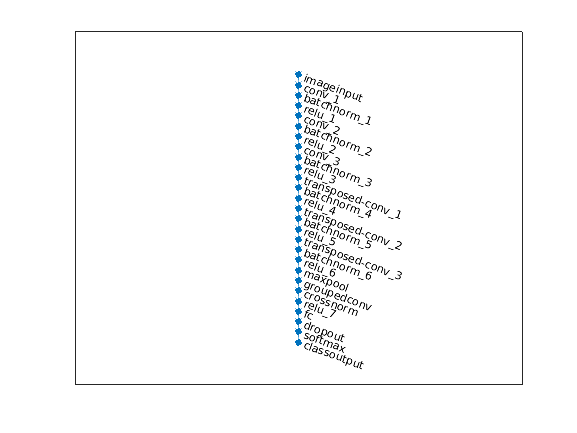

layers = [
    imageInputLayer([224 224 3],"Name","imageinput","Normalization","zscore")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],64,"Name","conv_2","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],128,"Name","conv_3","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    transposedConv2dLayer([3 3],128,"Name","transposed-conv_1","Cropping","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    transposedConv2dLayer([3 3],64,"Name","transposed-conv_2","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_3","Cropping","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same","Stride",[2 2])
    groupedConvolution2dLayer([3 3],1,"channel-wise","Name","groupedconv","Padding","same","Stride",[2 2])
    crossChannelNormalizationLayer(3,"Name","crossnorm")
    reluLayer("Name","relu_7")
    fullyConnectedLayer(2,"Name","fc")
    dropoutLayer(0.5,"Name","dropout")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
 
% Plot Layers
plot(layerGraph(layers));